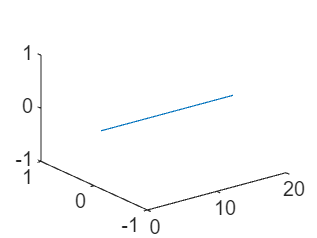

fig = figure;
ax = axes;

plot3(ax,1:20,zeros(1,20),zeros(1,20))
hold(ax,'on')

x = [10,11,12;...
    11,12,13;];
Y = [21.6e3,20e3,10e3;...
    30e3,15e3,12e3];

mean_Y = (Y(1,:)+Y(2,:))/2;

name_colormap = 'jet';
% interpolated_cmap = interpolateColor(mean_Y,name_colormap);

a = area(ax,x,Y,'LineStyle','none')

a =   1×3 Area 数组:

    Area    Area    Area


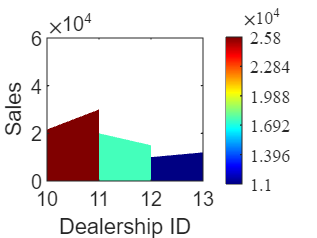

c =   ColorBar - 属性:

    Location: 'eastoutside'
      Limits: [11000 25800]
    FontSize: 9
    Position: [0.8318 0.1102 0.0381 0.8150]
       Units: 'normalized'

  显示 所有属性


colororder(ax,interpolated_cmap)
colormap(ax,name_colormap)
color_limits = [min(mean_Y),max(mean_Y)];
clim(ax,color_limits)
c = colorbar(ax);
c.Limits = color_limits;
c.FontName = 'Times New Roman';
c.Ticks = [min(mean_Y):(max(mean_Y)-min(mean_Y))/5:max(mean_Y)]

% 假设你有一列数据
data = [25.8,17.5,11]; % 你的数据，替换为实际的数据向量
interpolated_cmap = interpolateColor(data)

function interpolated_cmap = interpolateColor(data,map)
    arguments
        data
        map = 'jet'
    end
    % 确定数据的最小值和最大值
    data_min = min(data);
    data_max = max(data);
    
    cmap = colormap(map);
    % 将数据归一化到[0, 1]的范围
    normalized_data = (data - data_min) / (data_max - data_min);
    
    % 使用interp1进行插值
    cmap_size = size(cmap, 1); % 获取colormap的大小
    interpolated_cmap = zeros(length(data),3); % 初始化颜色矩阵，大小与数据相同
    for i = 1:length(data)
        % 对于每个数据点，找到对应的颜色
        cmap_index = normalized_data(i) * (cmap_size - 1) + 1;
        interpolated_cmap(i,:) = interp1(1:cmap_size, cmap, cmap_index);
    end
end
